
fm = 100;
x = @(t) cos(2 * pi * fm * t);

integrate(dirac)

Unrecognized function or variable 'dirac'.

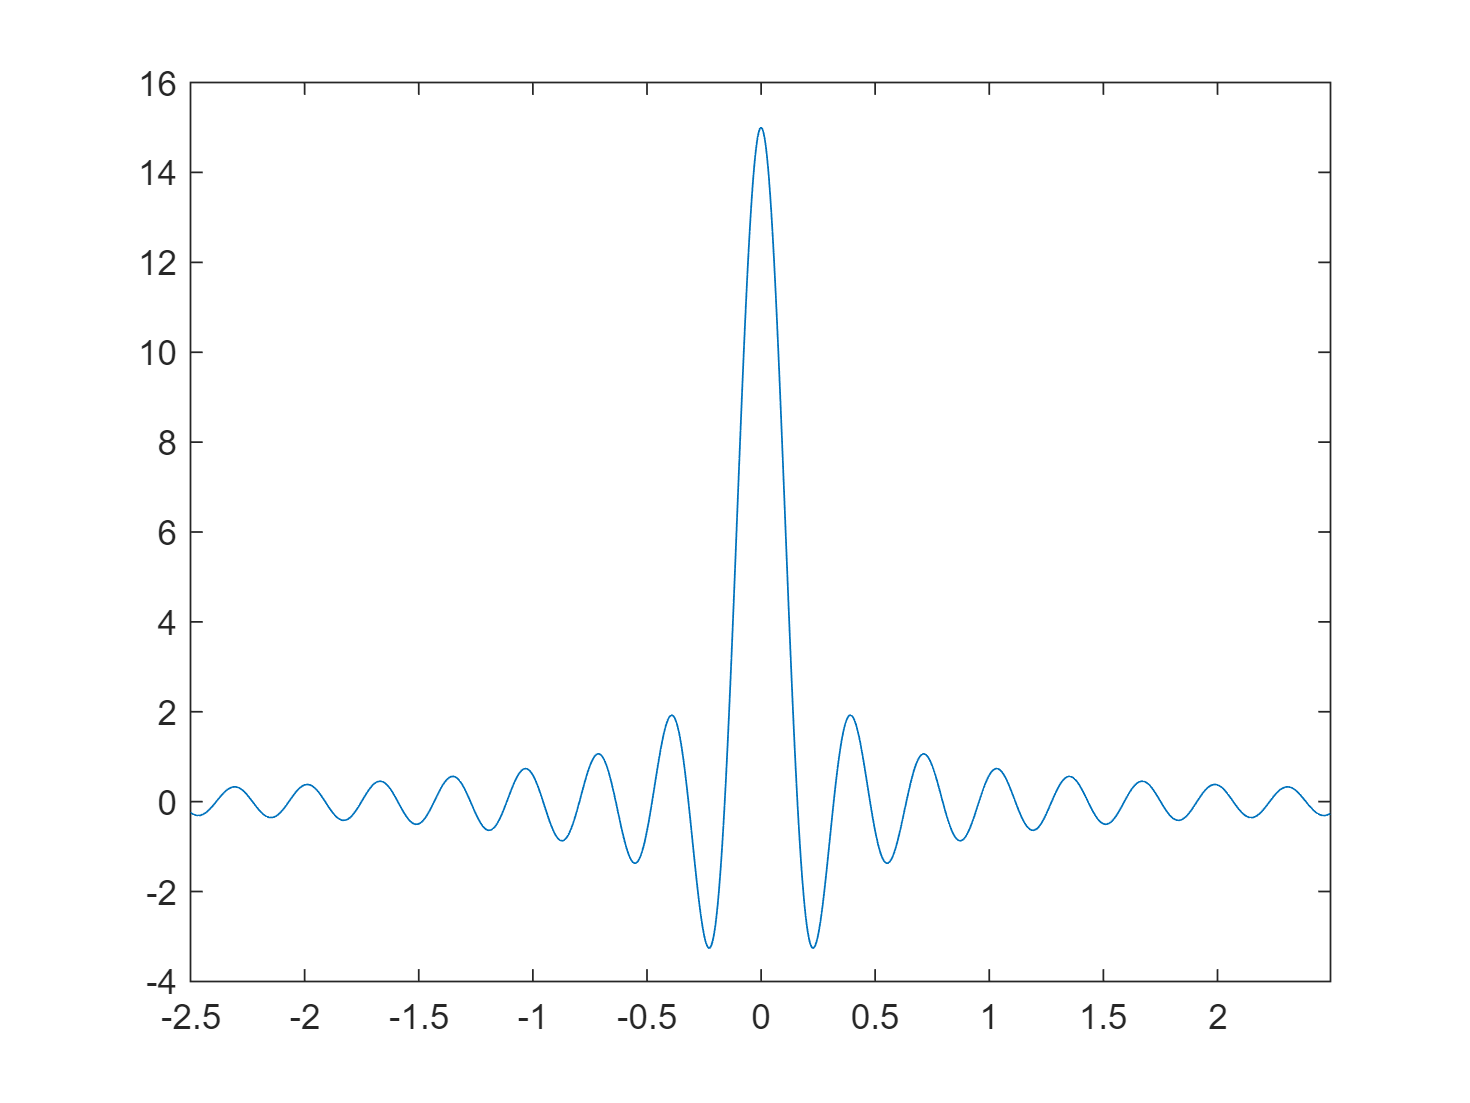


sampleRate = 50; % Samples per second
sampleInterval = 1 / sampleRate; % Interval of sample





Ts = 2;



T = 5;
fm = 1;
fs = 2 / T;

samples = 1000;

t = linspace(-T/2, T/2, samples + 1); t(end) = [];
x = 15 * sinc(2 * pi * fm * t);

figure
plot(t, x)
xlim([t(1) t(end)])

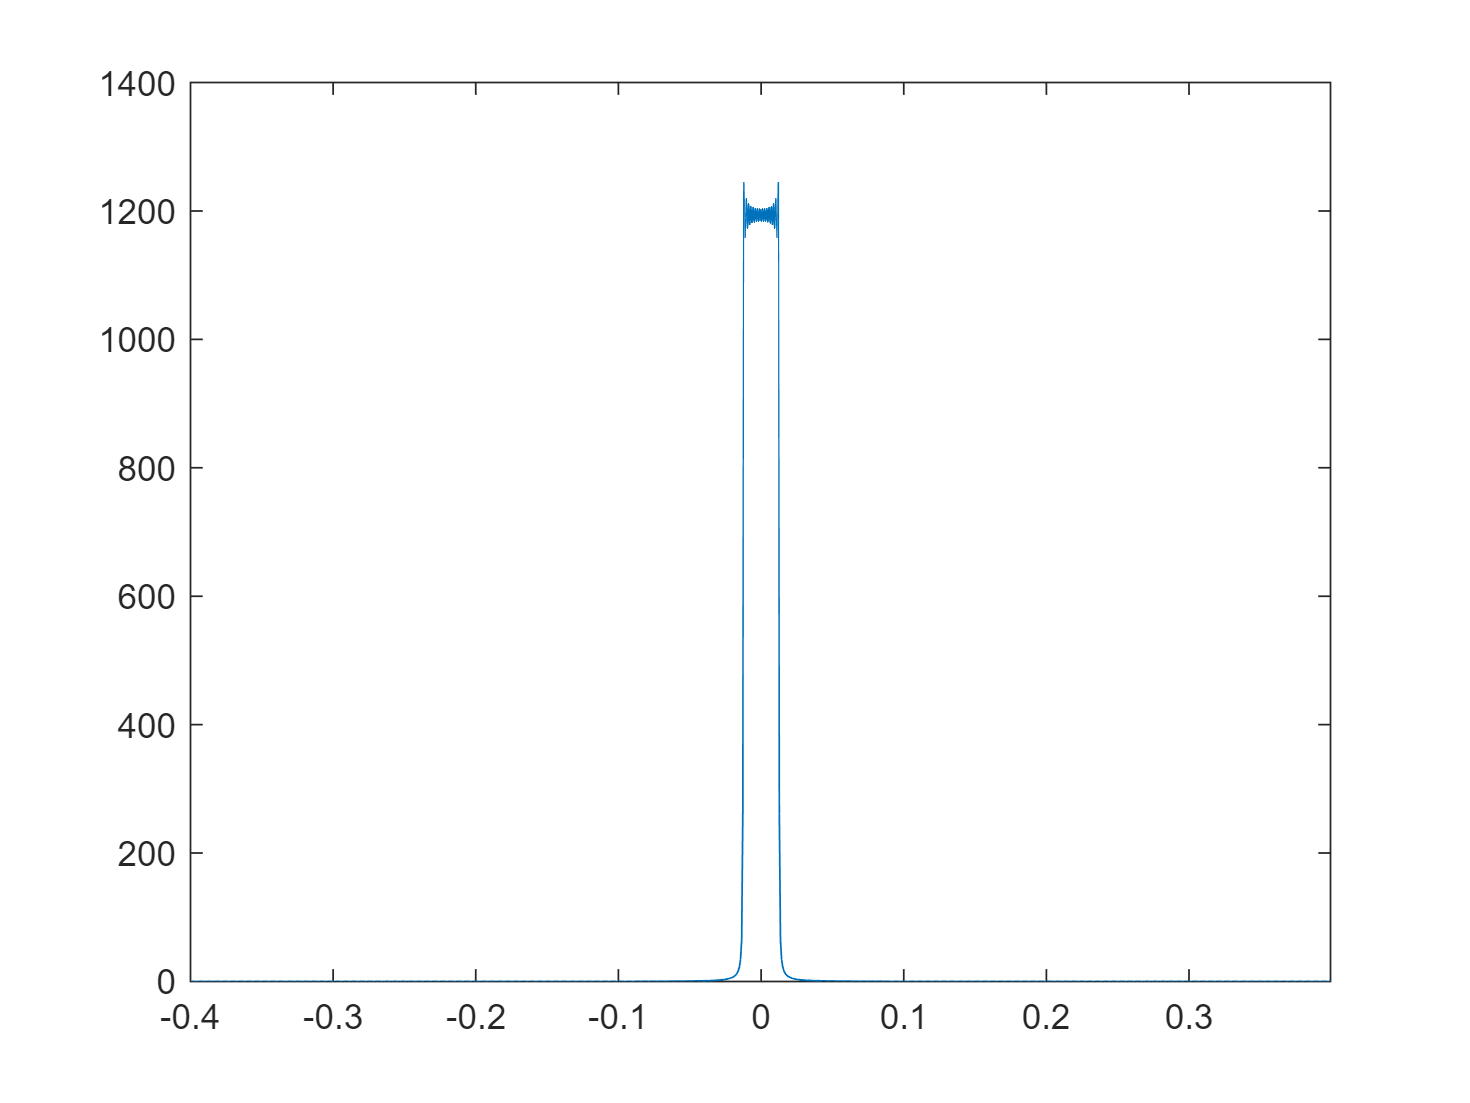


Ts = 1 / fs;
f = linspace(-fs, fs, samples + 1); f(end) = [];
X = fft(x, samples);
figure
plot(f, abs(fftshift(X)) * Ts)
xlim([f(1) f(end)])

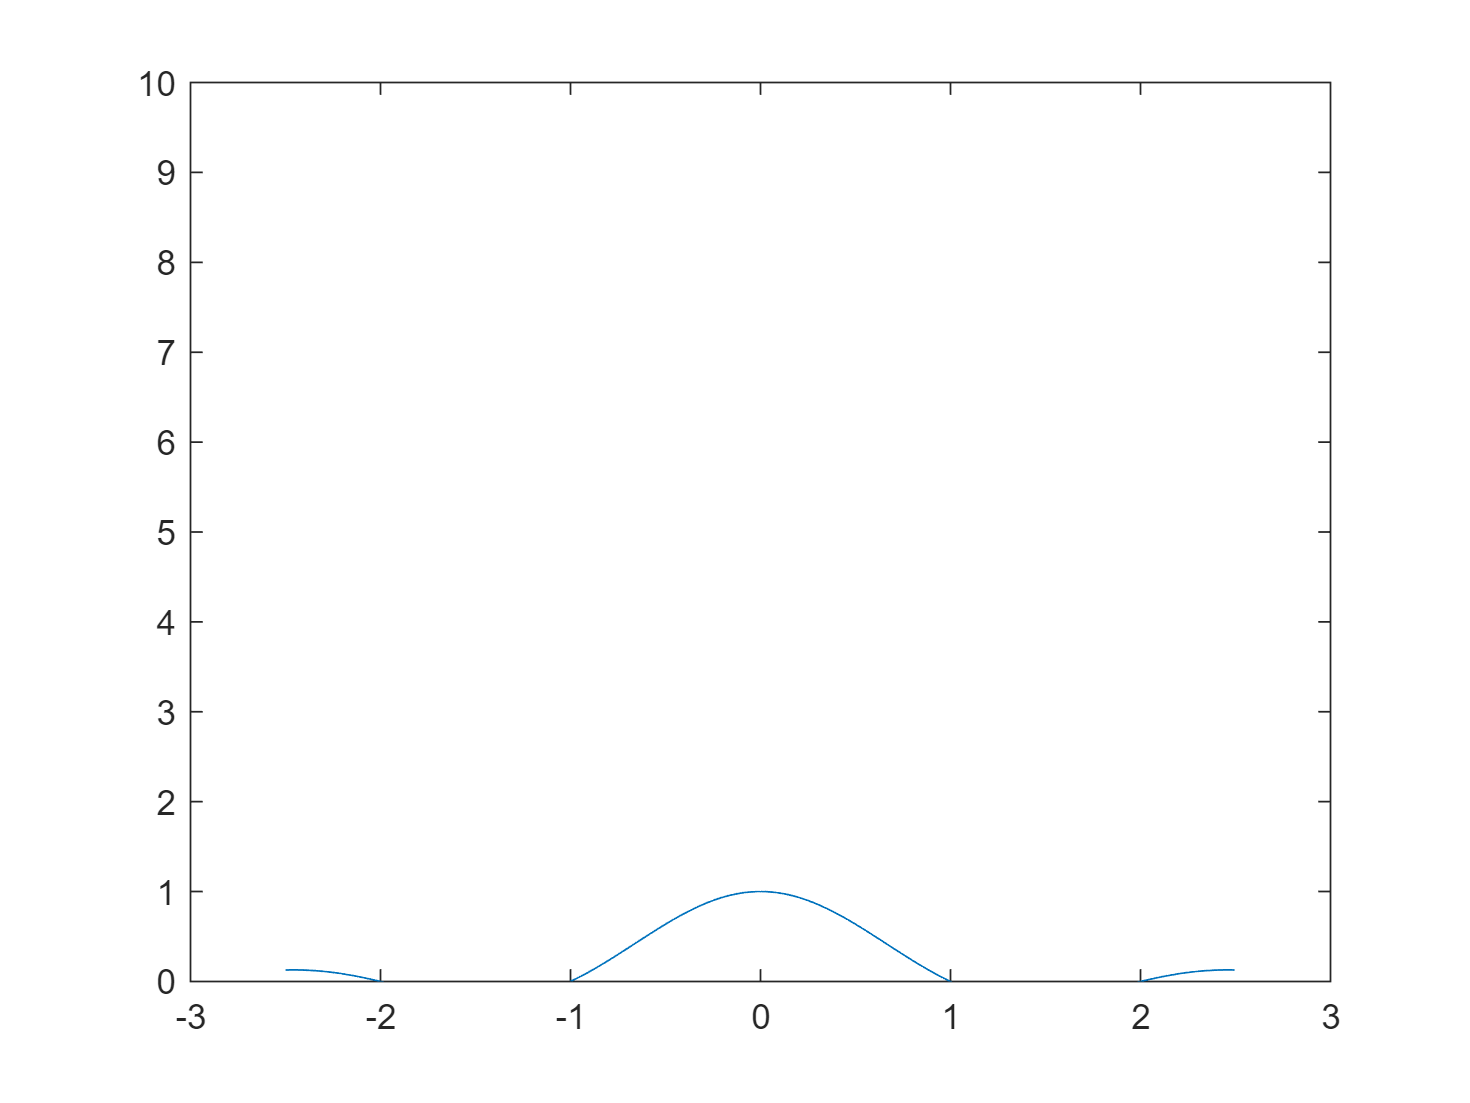

t = linspace(-T/2, T/2, samples + 1); t(end) = [];
y = sinc(t);
y1 = 1 ./ sinc(t);

figure
plot(t, y)
ylim([0, 10])

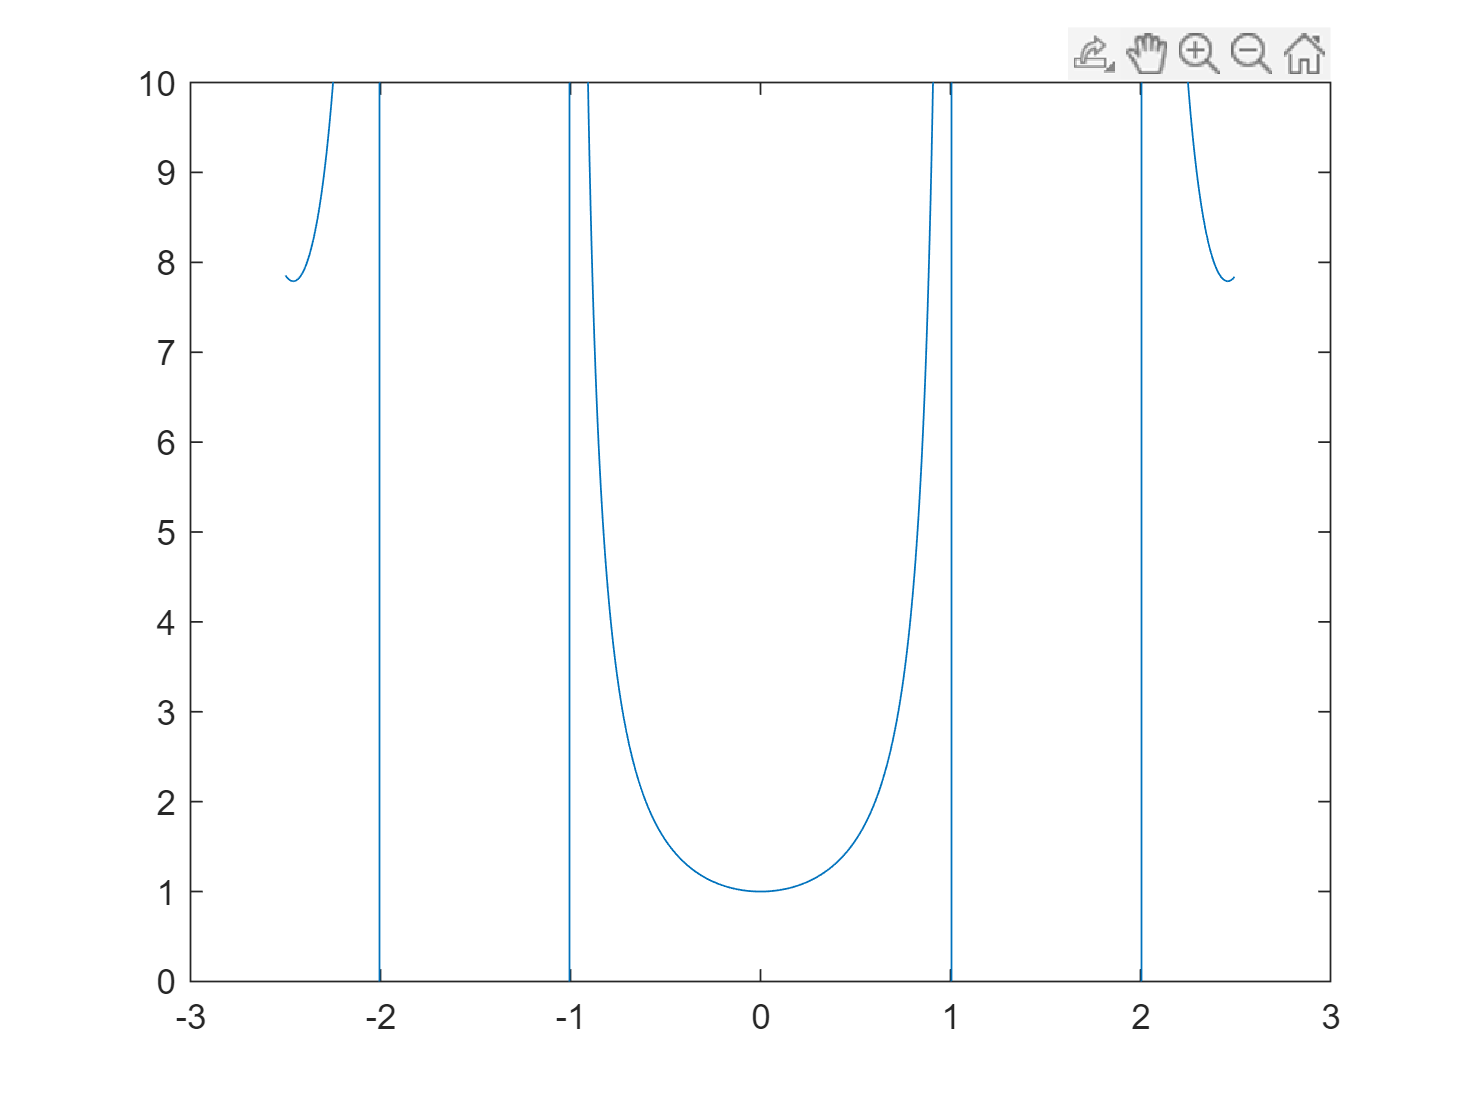


figure
plot(t, y1)
ylim([0, 10])

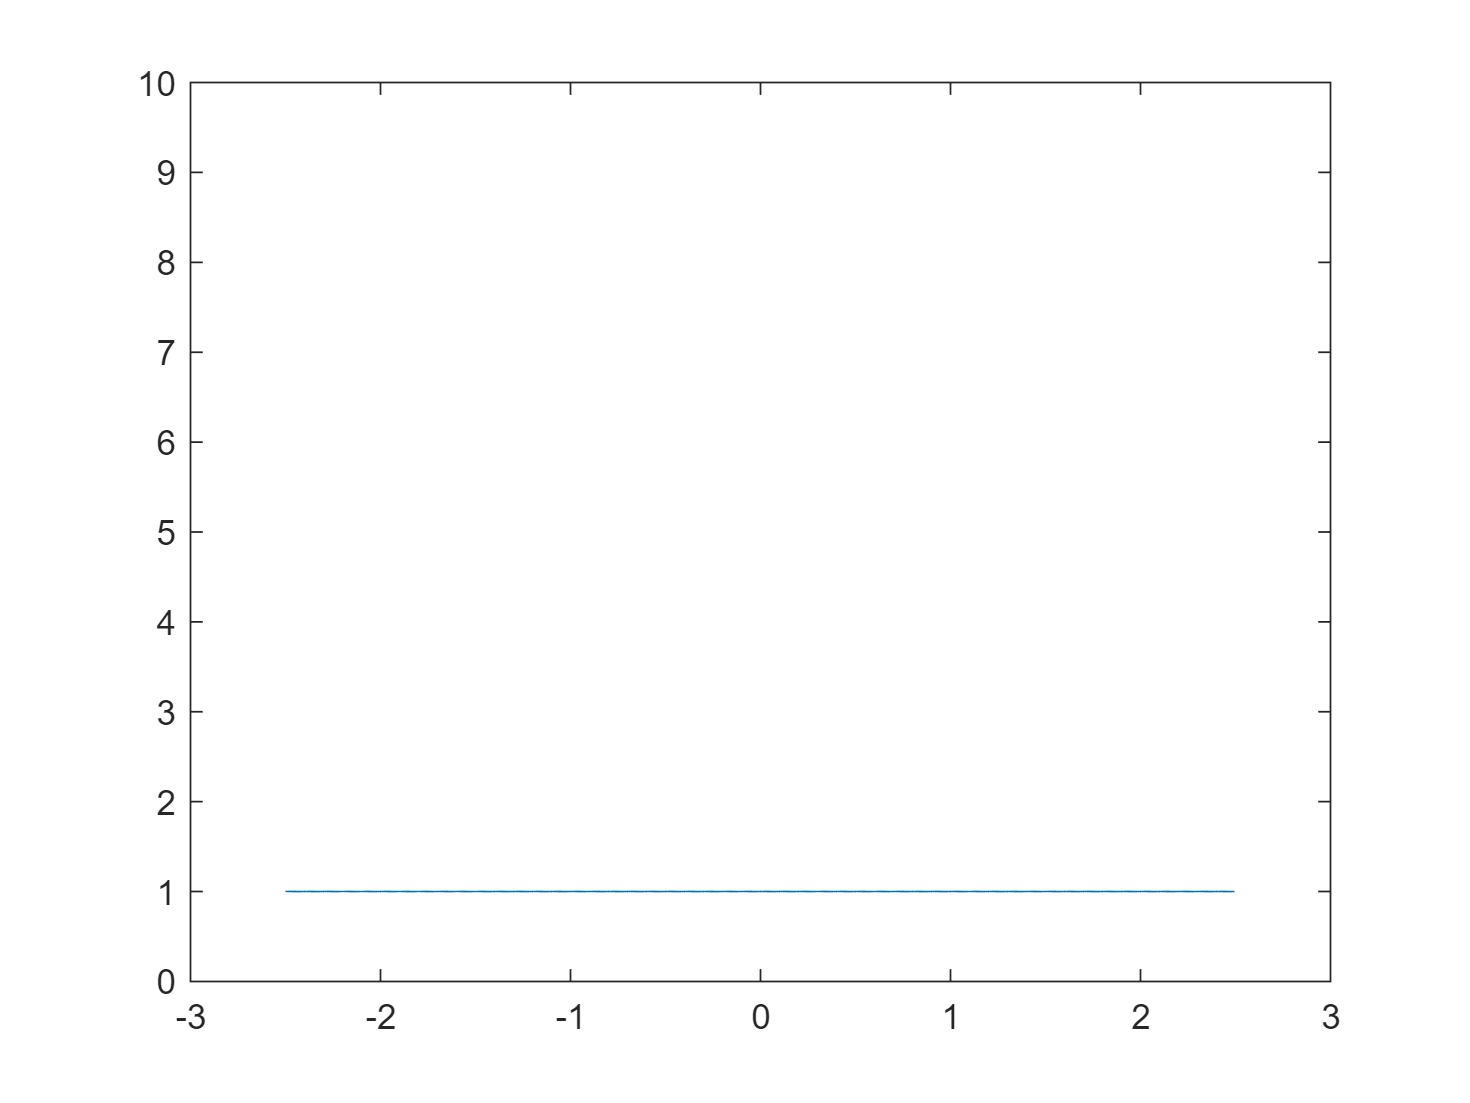


figure
plot(t, y .* y1)
ylim([0, 10])